# Treasure Hunt Game

Welcome to the MATLAB Treasure Hunt Module, designed to teach you how to make a fun treasure hunting game while learning some core Computer Science concepts along the way. We recommend that you complete our other module, Fundamentals of Programming, to help you better understand the ideas brought up in this module. We hope you enjoy it!

When it is finished, the game will look like this:

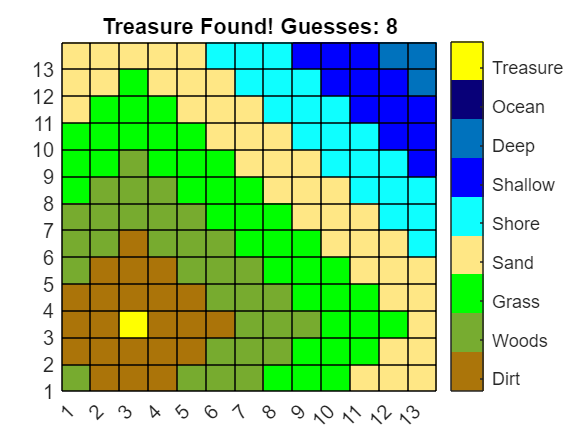

   At various points throughout this live script, you will be asked to check that your output matches the expected output. To do this, we recommend to remove the semicolons in your code and check the inline output for accuracy. Don't forget to put the semicolons back when you're done so that you can avoid unnecessary output!

  **Pro-tip**. This live script is split into sections so that you can run pieces of code one at a time. To run only the current section, we recommend using the "Run Section" button on the "Live Editor" tab of the toolstrip. If you prefer, there are also some other ways to run a section of code, which you can find [here](https://www.mathworks.com/help/matlab/matlab_prog/create-and-run-sections.html#mw_eb835312-5b90-4eb9-afa6-f189f42ccdce).

## Table of Contents

### Section 1: Creating Variables

### Section 2: Working with Matrices

### Section 3: Creating and Modifying Plots

### Section 4: User Input and If Statements

### Section 5: Creating and Using Functions

## Section 1: Creating Variables

Variables are a great way to store information to use later. Some of the information for this game we want to save includes the size of the treasure map, the treasure location, and the number of guesses the player has made.

### Your first variable

First, let's start by making a variable to represent the number of guesses the player has made. We want this variable to be equal to 0 because the player will have made zero guesses at the start of the game. 

  **Try**. Which of the following lines of code will create a variable called *numGuesses* that is equal to 0? Copy and paste the correct line of code into the code section below. If you choose the right line, you should see output stating "numGuesses = 0".

`       guessNum = 0`

`       0 = numGuesses`

`       numGuesses = 0`

  **Pro-tip**. A great way to name your variables is to use camel case. This means that the first word in your variable name is lowercase, while the rest of the words all begin with an uppercase letter. For example, if you wanted to name your variable "the coolest variable ever" using camel case, it would look like this: *theCoolestVariableEver*. You can read more about other common ways to name variables [here](https://www.theserverside.com/feature/A-guide-to-common-variable-naming-conventions).

% Paste the correct code here


### Let's make two more

Next, we want to choose the size of the treasure map. The treasure map will be a grid, so we can create the size by specifying the rows and columns. Let's start with a 15x15 map.

  **Try**. Create two variables called *rows* and *columns*, both equal to 15, to represent the row and column sizes. You should see output stating "rows = 15" and "columns = 15".

% Write your code here


### The numeric slider

If you want to allow the player to change the size of the board to make the game easier or harder, we can add a live control to make this quicker for them. You can add a slider to change the values and set bounds more easily.

First, find the CODE group under the LIVE EDITOR Tab.

Second, click the Control button and select Numeric Slider.

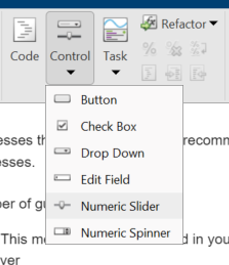

To edit the slider configurations, right click on the slider and select "Configure Control". We want to set the min to 6, the max to 20, the step to 1, and the Run to Nothing. You can set the label and default value to be whatever you like.

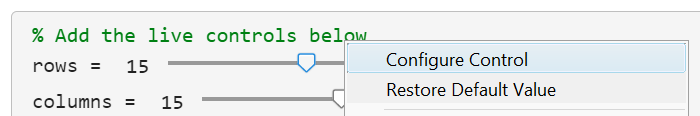

  **Try**. Use the same row and column variables from above and transform them into the Numeric Slider live control. Configure the controls as stated above. For now, set both sliders to 15 (you can change this later if you want to).

% Add the live controls below
rows = ;
columns = ;

### Making something new from something old

You can use old variables to make new ones. We want to create two new variables that are equal to 1 less than the row and column variables. These variables will be the actual boundaries of our treasure map.

  **Try**. Create two new variables called *limitC* and *limitR* that subtract one from the *columns* and *rows* variables, respectively.

% Write your code here


### Using your first built-in function

A built-in MATLAB function allows you to easily execute any kind of operation or task, such as generating new variables. The `randi` function will generate a pseudorandom integer between 1 and the number we specify. For example, if we want to generate a random integer between 1 and 10, we can run the following command. Notice that if you run it multiple times, you will see a different result each time.

randi(10)

Here is the documentation page where you can find more information about the `randi` function:

[Uniformly distributed pseudorandom integers - MATLAB randi (mathworks.com)](https://www.mathworks.com/help/matlab/ref/randi.html)

For the purposes of our game, we want to specify the maximum value to be the boundaries of our treasure map which we defined above. This will allow us to obtain random coordinates for our treasure chest.

  **Try**. Use the `randi` function to create two new variables corresponding to an X and Y location for the treasure, called *treasureX* and *treasureY*.

% Write your code here


## Section 2: Working with Matrices

MATLAB was originally created to help solve complex linear algebra problems involving matrices. A matrix is an r-by-c array of numbers, where r is the number of rows and c is the number of columns. We already specified our row and column lengths earlier, so now we can use those variables to create the matrix representing our entire treasure map.

### It's all full of zeros

To create our first matrix, we want to use a built-in MATLAB function called `zeros`. This function creates a matrix of zeros whose size is the determined by the two inputs you specify. In our case, we want the size to be equal to the *rows* and *columns* variables we made earlier. More information on the `zeros` function can be found here: 

[Create array of all zeros - MATLAB zeros (mathworks.com)](https://www.mathworks.com/help/matlab/ref/zeros.html#:~:text=X%20%3D%20zeros(%20sz%20)%20returns,2%2Dby%2D3%20matrix.&text=X%20%3D%20zeros(___%2C%20typename%20)%20returns%20an%20array%20of,%2C%208%2Dbit%20integer%200%20.)

  **Try**. Using the `zeros` function, create a new variable to represent our blank treasure map. Put in any size you'd like, run the code, and see the results. When you are done, set the size to be *rows* and *columns* - your output should be a matrix of zeros with dimensions equal to your *rows* and *columns *variables.

% Write your code here


### A blank map

Now that we have our map, let's use the `pcolor` function to visualize it. The `pcolor` function will display our matrix data as an array of colored cells. More information on the `pcolor` function can be found here: 

[Pseudocolor plot - MATLAB pcolor (mathworks.com)](https://www.mathworks.com/help/matlab/ref/pcolor.html)

  **Try**. Call the `pcolor` function on our map variable. If you called the function correctly, it should look like this: 

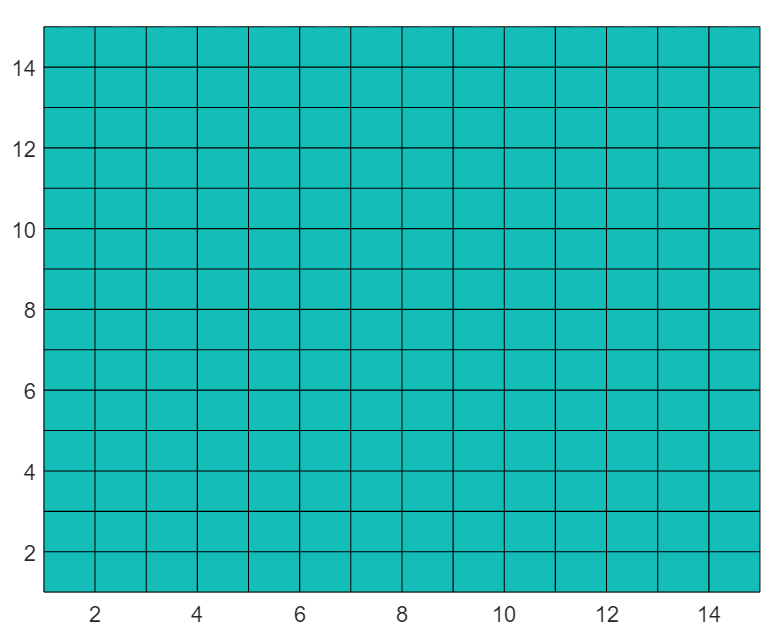

% Write your code here


### Not a number

Great! Now we have a map that is the correct size, but we want our blank map to be white instead of the teal color we saw above. To accomplish this, we'll need to learn about something called NaN.

NaN stands for Not a Number. In MATLAB, NaN is used to represent values that are not real or complex numbers; for example, the expression 0/0 will result in NaN. If you want to learn more about NaN, check out this external link:

[NaN - Wikipedia](https://en.wikipedia.org/wiki/NaN)

MATLAB interprets NaN values as white, and this is exactly what we want for our empty map, so we need MATLAB to go through our entire matrix of zeros and change each value to NaN. There is a neat trick we can use to do this called *logical indexing*, which you can see in the code below:

** Demonstration**. Run the below code and see how it changes the *map* matrix. 

map(map == 0) = NaN

This line of code is essentially saying "Find every value in *map* that is equal to 0, and set it equal to NaN". If you want to learn more about logical indexing, you can read more about it here, under the section titled "Logical Indexing":

[Logical Indexing - MATLAB](https://www.mathworks.com/company/newsletters/articles/matrix-indexing-in-matlab.html#:~:text=In%20logical%20indexing%2C%20you%20use,that%20are%20greater%20than%2012.)

Now let's try calling `pcolor` again and check that the map appears white.

  **Try**. Call the `pcolor` function on our updated map variable. It should now look like this: 

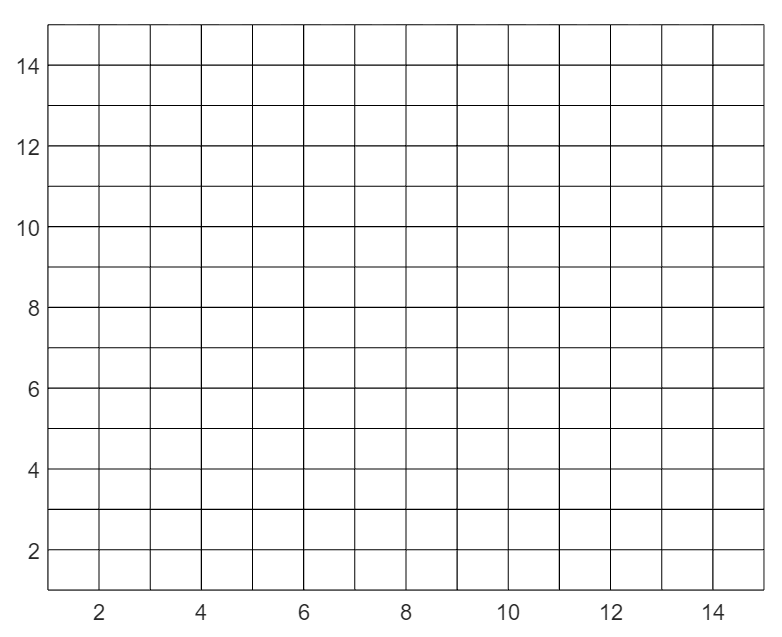

% Write your code here


### The coordinates

Now we want to map each of the points in our matrix to an X,Y coordinate so that we can store and plot the player's guesses. To do this, let's define two vectors: one which contains every possible X coordinate, and another which contains every possible Y coordinate.

  **Pro-tip**. Remember that we can define vectors by specifying the minimum and maximum values separated by a colon. For example, to define a vector called *v* containing every integer from 1 to 10, we could write `v = 1:10`

  **Try**. Define two new variables, called *xCoords* and *yCoords*, which contain all possible values of X and Y on our map.

% Write your code here


### Taxicab metric

Now that we have our treasure map and location, we want to calculate the distance from each coordinate point to our treasure. We can use the Taxicab Metric, also called Manhattan distance, to calculate the distance between two coordinate points. This external link provides some great insight into the Taxicab Metric: 

[Taxicab geometry - Wikipedia](https://en.wikipedia.org/wiki/Taxicab_geometry)

The Taxicab Metric requires us to find the absolute value. There is a built-in MATLAB function called `abs` that can do this for us. More information on the` abs` function can be found here: 

[Absolute value and complex magnitude - MATLAB abs (mathworks.com)](https://www.mathworks.com/help/matlab/ref/abs.html)

  **Try**. Equate this value: `abs(treasureY - xCoords) + abs(treasureX - yCoords)'`  to a variable called *finalMap.*

% Write your code here


% Display the map
disp(finalMap)

In this matrix, the 0 is the location of the treasure, and every other value represents the distance between that coordinate and the treasure. This distance is calculated by finding how far the coordinate is from the treasure in the x-direction, and then adding how far the coordinate is from the treasure in the y-direction.

### Saving colors

The last thing we want to do before setting up our plot is set the colors for our colormap. A colormap is a matrix containing values which represent how far away you are from the treasure. I chose nine different colors for my colormap. The last color should represent the treasure.

One of the ways that colors are represented in MATLAB is by their RGB value. RGB stands for Red, Green, Blue. All possible colors can be created depending on how much red, green, and blue you put into them.

An option to find the RGB values for the colors you want to use is to use a built-in MATLAB app called uisetcolor. You can type this into the MATLAB Command Window, and the app will pop up and let you pick colors. It will then output the RGB value for you to use. More information on uisetcolor can be found here:

[Open color picker - MATLAB uisetcolor (mathworks.com)](https://www.mathworks.com/help/matlab/ref/uisetcolor.html)

% Create the colormap for the board with different colors to simulate an island
cmap = [0.6706 0.4588 0.0392; 0.4667 0.6745 0.1882; 0 1 0;1 0.9059 0.5216;0.0588 1 1; 0 0 1; 0 0.4471 0.7412;0.0314 0 0.4706; 1 1 0];

## Section 3: Creating and Modifying Plots

By now, I'm sure you are sick of just looking at numbers and matrices and want to start plotting to make something pretty. 

### Add some pcolor

Now that we have our Taxicab matrix set up, we want to display all the values to start creating our treasure map. Let's use the `pcolor` function again to visualize a plot of our map. If you called the function correctly, it should look similar to the picture below.

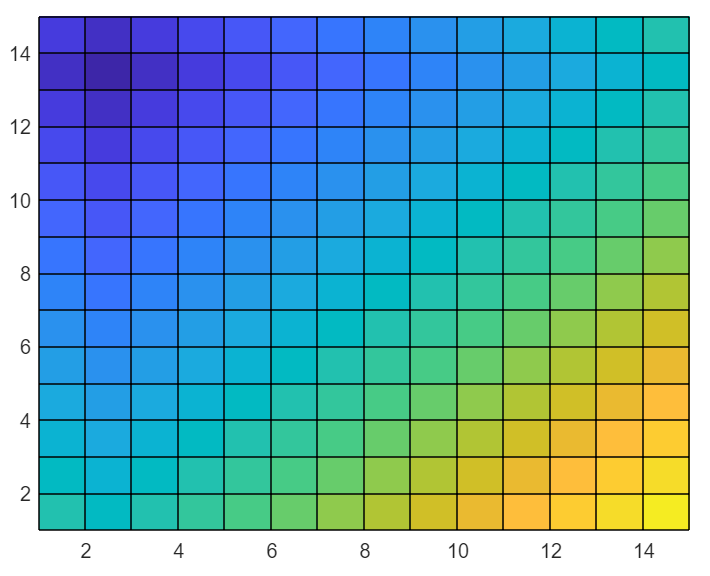

  **Try**. Call the `pcolor` function on the *finalMap* variable.

% Write your code here


### Colormap it up

Remember the colormap values that we picked earlier? Let's use those colors so that our plot looks like a map, instead of what we saw above. To do this, we can use the `colormap` function and input our colormap values from before as follows:

colormap(cmap);

Now the plot is using the colors you chose for your colormap, and the colors change depending on the distance from the treasure! But the treasure is not actually yellow, and some other squares are. Why is this happening?

### Colorbar to see our color

Let's include a colorbar to make it easier to see how the colors correspond to different values on our plot. Let's also define a variable to contain the colorbar so that we can edit it later if we want to. More information on colorbars can be found here:

[Colorbar showing color scale - MATLAB colorbar (mathworks.com)](https://www.mathworks.com/help/matlab/ref/colorbar.html)

 c = colorbar;

### Changing limits

If we look at the colorbar that MATLAB created, it tells us that the upper limit is 25 and the lower limit is 0. Remember, our Taxicab matrix contains all the distances from the treasure. Since the farthest point from the treasure on our map is 25, that is the highest value in the colorbar. But we don't want the farthest value to appear as yellow - only the treasure should be yellow!

In order to change this, we need to use the` clim `function to change our colormap limits. More information on the `clim` function can be found here:

[Set colormap limits (Renamed from caxis in R2022a) - MATLAB clim (mathworks.com)](https://www.mathworks.com/help/matlab/ref/clim.html)

Based on the size of our map, we'll want to set the upper limit to *rows*2 *and the lower limit to *0*. These limits will cover all of the values in our map, and now the maximum value will be greater than the farthest distance, meaning that nothing will appear as yellow.

  **Try**. Which of the following lines of code will set the upper limit of the colormap to *rows*2* and the lower limit to *0*? Copy and paste the correct line of code into the code section below. If you select the right answer, your plot should look something like the below image:

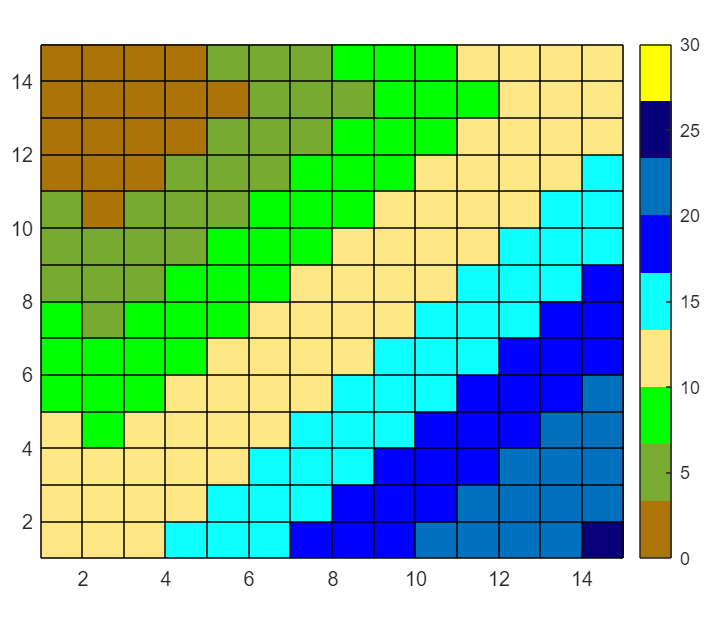

`       clim(0, rows*2)`

`       clim([0 rows*2])`

`       clim(0:rows*2)`

% Paste the correct code here


### Change the treasure

Now everything on the map looks good, except that we can't see the treasure! Looking at the colorbar, which number corresponds to yellow? Fill in the missing piece of the code below with that number. If you choose the correct value, you should see the treasure appear as yellow.

finalMap(treasureX, treasureY) = ; % Insert the correct value here
pcolor(finalMap);

### Hold on

Now we can see the treasure, but you may have noticed that everything we did above, like adding the colorbar and changing its limits, is gone. That is because we had to re-plot our map after we changed the value of the treasure, and this overwrote everything else we had added to our plot! If we want to retain our changes even after re-plotting, we need to use the "hold on" command. More info about this command can be found here:

[Retain current plot when adding new plots - MATLAB hold (mathworks.com)](https://www.mathworks.com/help/matlab/ref/hold.html)

Run the code below to re-add everything we lost, and activate the "hold on" command so that this won't happen again.

hold on;

colormap(cmap);
c = colorbar;
clim([0 rows*2]);

### Labeling the color

It will make it easier for players to interpret our colorbar if we add labels to it. To do this, we need to use the colorbar variable we made earlier and access the TickLabels property from it. We can do this with the following statement: *var.TickLabels*. These were the values I used for my TickLabels: 

{'Dirt', 'Woods', 'Grass', 'Sand', 'Shore', 'Shallow', 'Deep', 'Ocean', 'Treasure'}

You are welcome to change them if you like; just make sure the number of labels is equal to the number of colors you chose. Your colorbar should now look like this: 

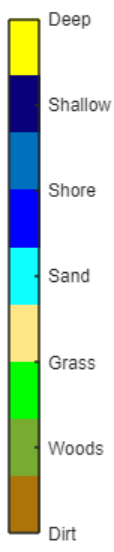

c.TickLabels = {'Dirt','Woods','Grass','Sand','Shore','Shallow','Deep','Ocean','Treasure'};

### Fix the space

You may have noticed that the labels in our colorbar do not correspond to the right colors. Fortunately, the colorbar variable has a property called Ticks that can fix this. We can use the syntax *var.Ticks* to access and change this property.

We can set the Ticks property using three numbers. The first number is the minimum value, the second number is the tick spacing, and the third number is the maximum value.

We have already selected our minimum and maximum values, so we'll set those to the same ones we chose earlier. But what value should we choose for the spacing? We want to choose a value such that the labels will be evenly spaced, and each label will correspond directly to one color.

  **Try**. Which of the following values will set the spacing so that each label will correspond with the right color? Copy and paste the correct code into the code section below. If you select the right answer, your plot should look something like the below image:

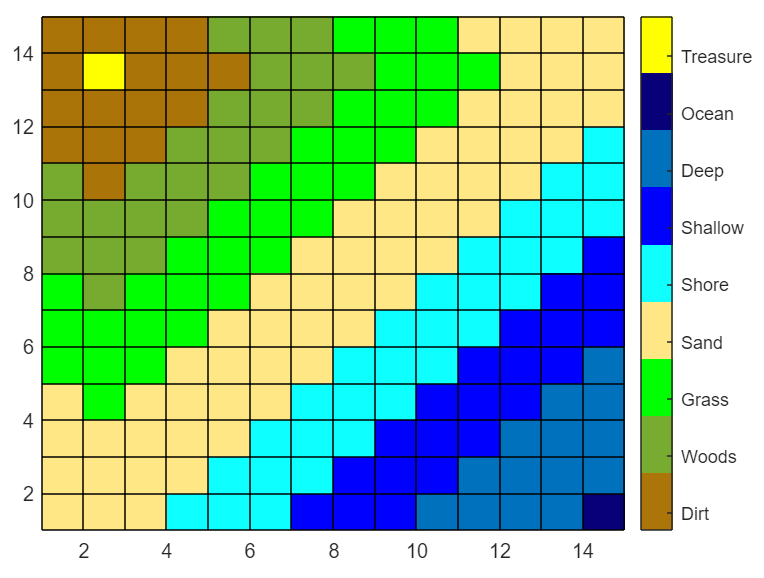

`       9`

`       rows * 2`

`       (rows * 2) / 9`

min = 1;
spacing = ; % Paste the correct code here 
max = rows*2;

c.Ticks = min:spacing:max;

### Ticks tock

Now that we have our colorbar set up, let's make our x and y axes look better. Similar to how we set the ticks for the colorbar, we can also set ticks for the x and y axes. There are functions called `xticks` and` yticks` that will let us do this quickly. For the input of the function, we give it three numbers separated by colons the same way we did for the Ticks property of the colorbar above. The three numbers in order are the minimum, the spacing, and the maximum. More information on these functions can be found here:

[Set or query x-axis tick values - MATLAB xticks (mathworks.com)](https://www.mathworks.com/help/matlab/ref/xticks.html)

Try playing around with these numbers. When you are done, I recommend setting the min to 1, the spacing to 1, and the max to the *limitC* and *limitR* value that you chose above, respectively (*limitC* for the X-axis and *limitR* for the Y-axis). Your plot should look like this when done:

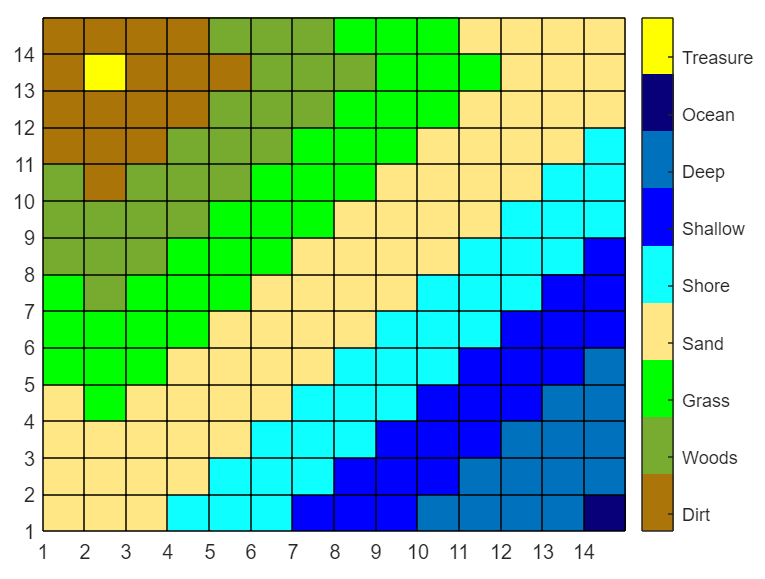

% Write your code here


### Title time

Finally, we should add a title to help instruct the player on what they should do. MATLAB has another built-in function to do just that called `title`. Just call the `title` function, and the input will take a string of what you want it to say. I chose to say, *"Find the Treasure!"*. More info on the` title` function can be found here:

[Add title - MATLAB title (mathworks.com)](https://www.mathworks.com/help/matlab/ref/title.html)

The title should look like this:

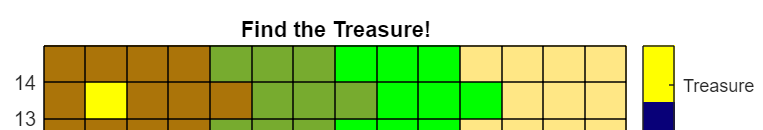

% Write your code here


Now we have our final map! Next, we will need to write some code so that people can actually play the game.

## Section 4: User Input and If Statements 

When making a game, you will need to gather some input from the user. This could include mouse clicks, button presses, or keyboard strokes. In the case of our treasure hunt game, we want to take in two numbers representing the player's x and y coordinate guess. 

### Guess what

Let's make two new variables to keep track of the player's guess.

  **Try**. Create two new variables, called *guessX* and *guessY*, and set them both equal to 1.

% Write your code here


### Live guessing

It will get annoying for the user to delete and type in a new guess every time, and we want to make sure they are guessing within the bounds of our plot. Let's use another live control called "Numeric Spinner" to avoid these issues. Remember that we can add live controls by clicking the "Control" button in the "Live Editor" section of the toolstrip.

  **Try**. Add two Numeric Spinner live controls to the code section below. For each one, right click on it and select Configure Control. There, we can set the label, set the min to 1, set the max to limitC and limitR, respectively, and set Run to Nothing. Start by setting *guessX* to 6 and *guessY *to 4.

% Add the live controls below
guessX = ;
guessY = ;

### Put in one guess

Now that we have the user's guess, we need to show where their guess is by updating it on our plot. Remember that we have two maps: *map* is the blank map we created using NaN values, and *finalMap* is the map we were working on earlier, which now looks something like this:

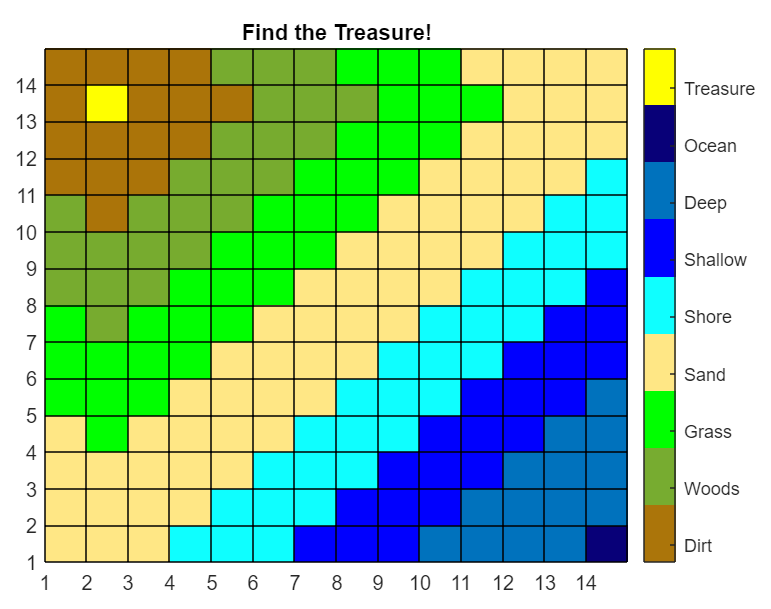

We don't want the player to see this yet - they have to guess where the treasure is first! For now, we only want to show them the blank map, with their guess revealed. To do this, we need to index into *map* and change the value at the spot they guessed to the corresponding value from *finalMap*. Run the code below to do this, and then plot *map* to see the user's guess revealed.

  **Pro-tip**. MATLAB matrix indexing works the opposite way of traditional X,Y grid indexing. Therefore to show the correct guess, we need to input the guess in the order (Y,X) instead of (X,Y). More information on matrix indexing in MATLAB can be found here:

[Matrix Indexing in MATLAB - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/company/newsletters/articles/matrix-indexing-in-matlab.html)

% Set the value of "map" at coordinates (guessX, guessY) to the value of
% "finalMap" at those coordinates
map(guessY, guessX) = finalMap(guessY, guessX);

% Call pcolor on the "map" variable
pcolor(map);

### Hold off

Wait! We just plotted *map*, which should just be a bunch of white squares, but instead the output looks like *finalMap* - why is this happening?

Remember that earlier, we ran the "hold on" command, which means that every time we plot something new, it will add onto what we have already plotted instead of replacing it. But now we *do* want a new plot, and it turns out that there is a similar command to "hold on" which can accomplish this: the "hold off" command. Let's run that command and then re-run the commands from above to set up our plot - now we should see only the user's guess revealed:

hold off;
pcolor(map);
hold on;
colormap(cmap);
c = colorbar;
clim([0 rows*2]);
c.TickLabels = {'Dirt','Woods','Grass','Sand','Shore','Shallow','Deep','Ocean','Treasure'};
min = 1;
spacing = (rows * 2) / 9;
max = rows*2;
c.Ticks = min:spacing:max;
xticks(1:1:limitC);
yticks(1:1:limitR);
title("Find the Treasure!");

### If and else

Congratulations! You've officially taken your first guess and plotted the result on the map. Now, there are a few other things we need to take care of before our game is completely functional, and this will rely on "if statements". An if statement is a statement that will only execute the code inside it if the statement is true. 

You can remind yourself how to use if statements here: 

[Execute statements if condition is true - MATLAB if elseif else (mathworks.com)](https://www.mathworks.com/help/matlab/ref/if.html)

Below is an example of an if statement in MATLAB. It will output "Too Small" if the value *testNum* is less than 10, otherwise it will output "Perfect".

  **Try**.  Change the value of testNum and see how the output changes. 

testNum = 0;

if (testNum < 10)
    testNum = "Too Small"
else
    testNum = "Perfect"
end

Back to our game, let's use our *numGuesses* variable from earlier to see if the player has made a guess already. For the if statement's expression, we want to check if *numGuesses* is greater than zero. If *numGuesses* is zero, that means we have not yet started the game. Let's put the *guessX* and *guessY* live controls inside the if statement. We also want to update *map* and call pcolor again to update the player's guess.

  **Try**. Run this section to see if there is any output.

  **Pro-tip**. Include your expression inside parentheses to make it easier to read.

if(numGuesses > 0)
    guessX = 5;
    guessY = 3;

    % Upadate the NaN matrix
    map(guessY,guessX) = finalMap(guessY,guessX);

    % Show the update
    pcolor(map);
end

 **Reflect**. When you tried running the section above, you should have noticed that it does not produce any output. This is because the value of numGuesses is already set to zero. Therefore, MATLAB will not execute the code inside the if statement because its expression is not true. In its current state, the value of *numGuesses* never changes, so let's add an else statement and increment the value of *numGuesses* inside it so the game can start. 

  **Try**. Add an else statement to increment the value of *numGuesses* by one.

  **Pro-tip**. The else statement shares the end statement with the if statement.

if(numGuesses > 0)
    guessX = 5;
    guessY = 3;

    % Upadate the NaN matrix
    map(guessY,guessX) = finalMap(guessY,guessX);

    % Show the update
    pcolor(map);
else
    % Write your code here
    
end

Now we can start the game, but *numGuesses* will always be stuck at 1. We also want it to increase for every guess the player makes, so let's add some code to do that.

  **Try**. Increment numGuesses inside the if statement so we can keep track of how many guesses the player has made.

if(numGuesses > 0)
    guessX = 11;
    guessY = 3;

    % Update the NaN matrix
    map(guessY,guessX) = finalMap(guessY,guessX);

    % Show the update
    pcolor(map);
    
    % Write your code here
    
else
    numGuesses = numGuesses + 1;
end

### Check for the treasure

Great job! Now we can make as many guesses as we want, and our game is almost completely playable. We just need to check if the player found the treasure to end the game. To do this, we must add an if/else statement inside our previous if statement to check whether the treasure has been found. If it has, we want to call pcolor on our Taxicab matrix to reveal the entire treasure map, and we want to change the title to say "Treasure Found!". You can also include a message to the player if you would like (for example, you can use *numGuesses* to tell the player how many guesses it took them to find the treasure).

  **Try**. Add an if/else statement into our current if statement. The expression for the if statement should check if *guessX* is equal to *treasureX* and if *guessY* is equal to *treasureY*. If both of these are true, we want to fill in the whole plot with the Taxicab matrix and change the title to "Treasure found!". Once you've done this, you can continue to submit guesses until you find the treasure. The game is now completely playable!

  **Pro-tip**. Use a double ampersand (&&) to combine two expressions into one if statement. 

if(numGuesses > 0)
    guessX = 12;
    guessY = 9;

    % Write your code here


    numGuesses = numGuesses + 1;
else
    numGuesses = numGuesses + 1;
end

## Section 5: Creating and Using Functions

We have used many built-in MATLAB functions to build this game, but did you know that you can also create your own? It is important to make your own function when you have code that will be executed multiple times with different inputs. 

More information on declaring your own functions can be found here:

[Declare function name, inputs, and outputs - MATLAB function (mathworks.com)](https://www.mathworks.com/help/matlab/ref/function.html)

### Your first function

  **Try**. In the empty code section at the bottom of this script, in the section called "Function junction", try creating your own function called *addFive* that adds 5 to an inputted number and returns the result. Then try giving different inputs to the line of code below to see if it works! 

  **Pro-tip**. Notice that we must define the function at the bottom of the script, after we call it.

addFive(3)

### A more useful function

Now that you know how to define a function, let's create one that helps us to play the game!

  **Try**. At the bottom of this script, in the section called "Function to play the game", there is an outline of a function that has not been fully implemented. Follow the instructions in the comments of the function to fill in the missing parts. If youget stuck or want to check your answers, you can find a fully implemented version of this function in the file "treasureHuntTest.mlx".

### Function junction

Write your function definition here:

function result = addFive(num)
    result = num + 5;
end

### Function to play the game

Fill in the missing pieces of the function below:

function playGame(treasureX,treasureY,map,finalMap,guessX,guessY,numGuesses)
    % If the treasure has been found
    if(guessX == treasureX)&&(guessY == treasureY)
        % Add a line of code here to display the finalMap


        % Add a line of code here to change the title to say "Treasure Found!"


    % If the treasure has not been found
    else
        % Add a line of code here to set map(guessY,guessX) equal to
        % finalMap(guessY,guessX)


        % Add a line of code here to display the map

        
        % This code will tell the player how far they are from the
        % treasure, and how many guesses they've taken so far. See if you
        % can understand how it works!
        help = "You are " + string(finalMap(guessY,guessX)) + " away from the treasure.";
        guess = "Guess: " + numGuesses;
        disp(help);
        disp(guess);
        disp("Guess again!");
    end
end